# Lab 6 Report

12210309 LI Zhiying

## Problem 1 - Convolutional operations

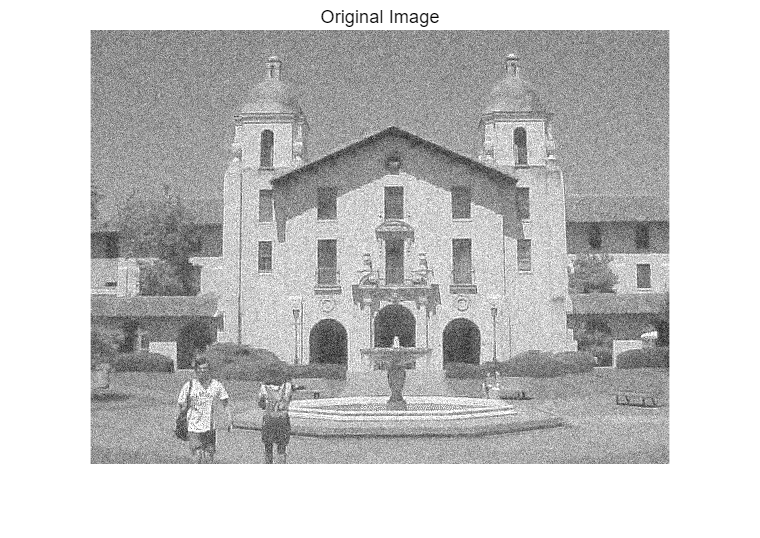

clc; clear; close all;
f = fopen("lab6prob1data");
a = fread(f,[580,inf],"uint8");
img = a';
imshow(uint8(img));
title('Original Image');

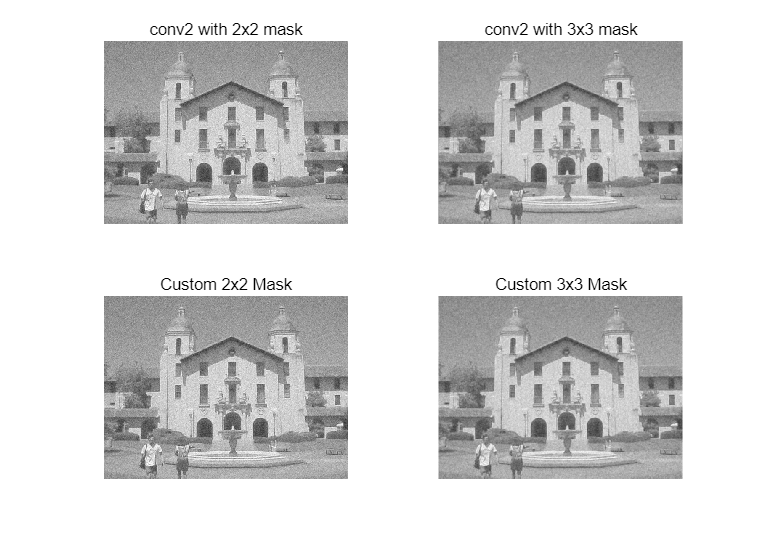


% i
mask_2x2 = ones(2, 2);
mask_3x3 = ones(3, 3);

conv2_2x2 = conv2(double(img), mask_2x2, 'same') / sum(mask_2x2(:));
conv2_3x3 = conv2(double(img), mask_3x3, 'same') / sum(mask_3x3(:));

custom_2x2 = custom_conv2(double(img), mask_2x2);
custom_3x3 = custom_conv2(double(img), mask_3x3);

subplot(2,2,1);
imshow(uint8(conv2_2x2));
title('conv2 with 2x2 mask');

subplot(2,2,2);
imshow(uint8(conv2_3x3));
title('conv2 with 3x3 mask');

subplot(2,2,3);
imshow(uint8(custom_2x2));
title('Custom 2x2 Mask');

subplot(2,2,4);
imshow(uint8(custom_3x3));
title('Custom 3x3 Mask');

*Answer： ***掩码大小对模糊和降噪的影响**

**1.2x2 掩码**: 相对较小，减少了噪声但保持了更多的细节。

**2.3x3 掩码**: 提供了更强的模糊效果，可以更好地减少噪声，但图像会失去更多细节。

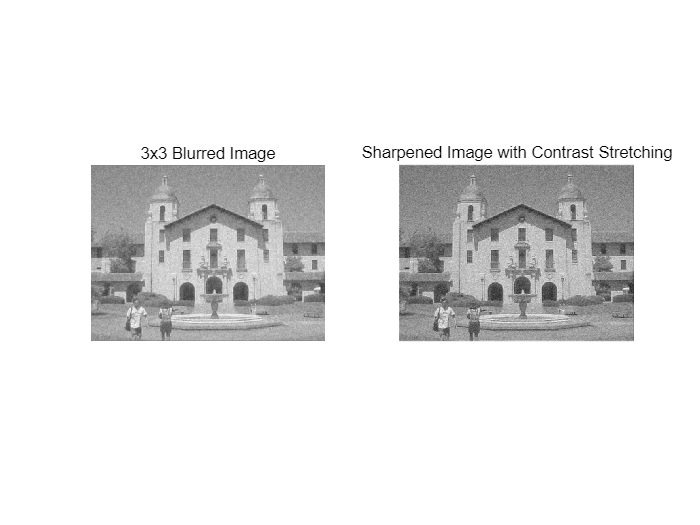

% ii
laplacian_mask = [0 -1 0; 1 5 -1; 0 -1 0];
sharpened_img = conv2(conv2_3x3, laplacian_mask, 'same');
sharpened_img_stretched = contrast_stretch(sharpened_img);

figure;
subplot(1,2,1);
imshow(uint8(conv2_3x3));
title('3x3 Blurred Image');

subplot(1,2,2);
imshow(sharpened_img_stretched);
title('Sharpened Image with Contrast Stretching');

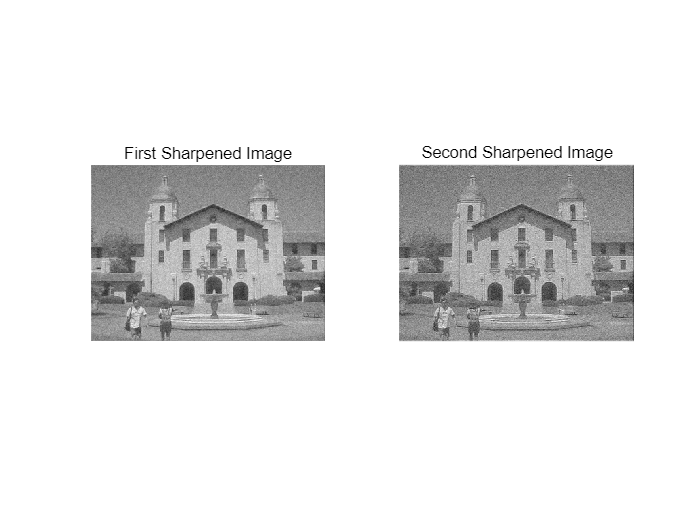

% iii
second_sharpened_img = conv2(sharpened_img_stretched, laplacian_mask, 'same');
second_sharpened_img_stretched = contrast_stretch(second_sharpened_img);
figure;
subplot(1,2,1);
imshow(sharpened_img_stretched);
title('First Sharpened Image');

subplot(1,2,2);
imshow(second_sharpened_img_stretched);
title('Second Sharpened Image');

*Answer: *重复的锐化可以增加图像的清晰度和边缘的对比度，使边缘细节更加突出，有助于一些特征的识别。但多次锐化也可能导致噪声放大

img_target = sharpened_img_stretched;
% iv
imgzoom_1 = imresize(img_target,2,'bilinear');
imgzoom_1 = conv2(imgzoom_1,laplacian_mask);
imgzoom_1_stretch = contrast_stretch(imgzoom_1);
figure;
imshow(imgzoom_1_stretch);

% v
imgzoom_0 =  imresize(img_target,2,'nearest');
imgzoom_0 = conv2(imgzoom_0,laplacian_mask);
imgzoom_0_stretch = contrast_stretch(imgzoom_0);
figure;
imshow(imgzoom_0_stretch);

## Problem 2  Shot noise

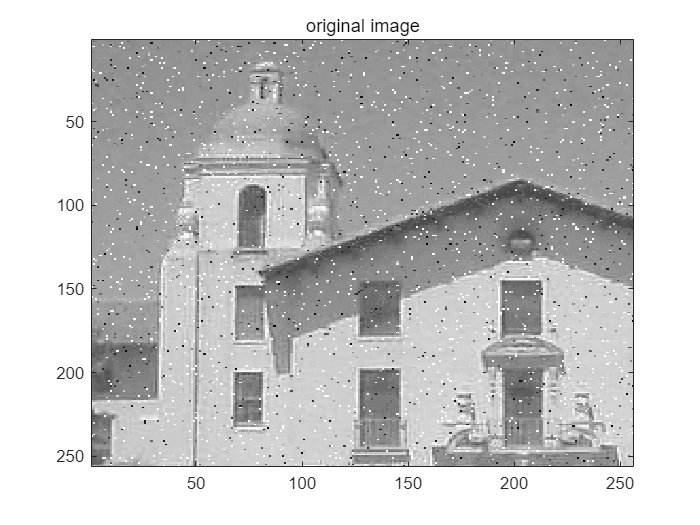

clc;clear;close all;
f2=fopen("lab6prob2data");
a =fread(f2,[256,inf],'uint8');
img= a';
figure;
imagesc(img);
colormap('gray');
title('original image');

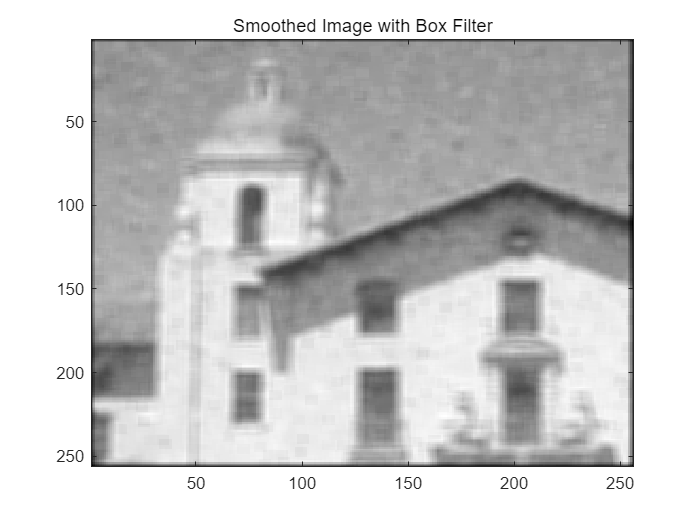

% i 
box_filter = ones(6,6); 
smoothed_img = conv2(img, box_filter, 'same');
figure;
imagesc(smoothed_img);
colormap('gray');
title('Smoothed Image with Box Filter');

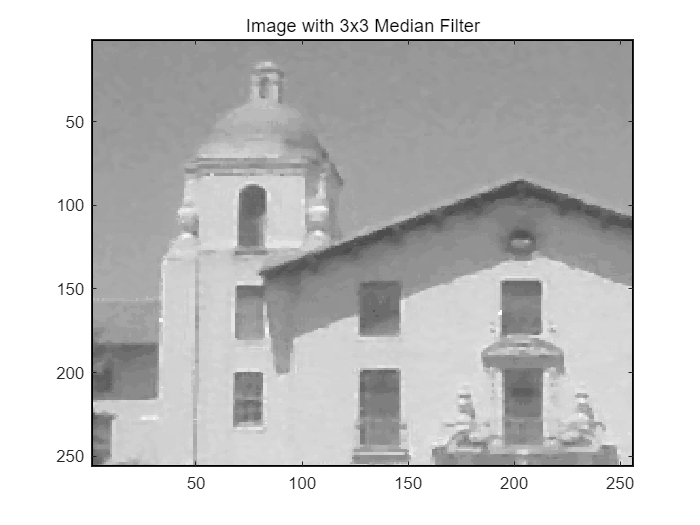


% ii
median_filtered_img = median_filter(img);
figure;
imagesc(median_filtered_img);
colormap('gray');
title('Image with 3x3 Median Filter');

*Answer: *就图像质量而言，3×3中值滤波器更令人满意。

## Problem 3 Experimenting with Filters 

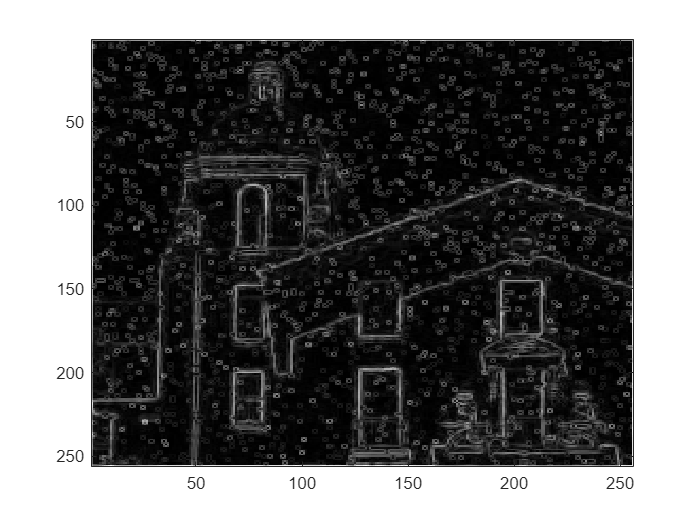


edge_filter_horizontal = [
    -1 -2 -1;
     0  0  0;
     1  2  1
];
edge_filter_vertical = [
    -1  0  1;
    -2  0  2;
    -1  0  1
];
horizontal_edges = conv2(double(img), edge_filter_horizontal, 'same');
vertical_edges = conv2(double(img), edge_filter_vertical, 'same');
edge_detected_img = sqrt(horizontal_edges.^2 + vertical_edges.^2);
figure;
imagesc(edge_detected_img);
colormap('gray')

*Answer: *使用水平和垂直方向的卷积核来强调图像中的边缘。水平和垂直滤波器分别对两个方向的边缘进行响应，然后通过合并这两个方向的结果，突出了图像的轮廓

## Problem 4 Power spectrum

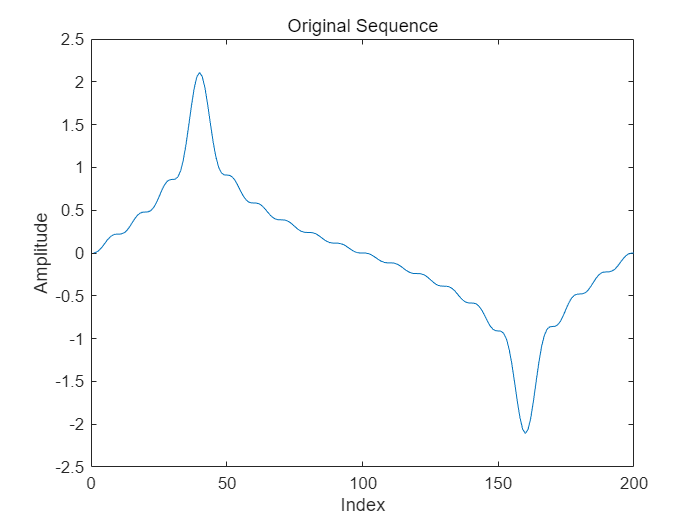

data = load('lab6prob5data');

% i
figure;
plot(data);
title('Original Sequence');
xlabel('Index');
ylabel('Amplitude');

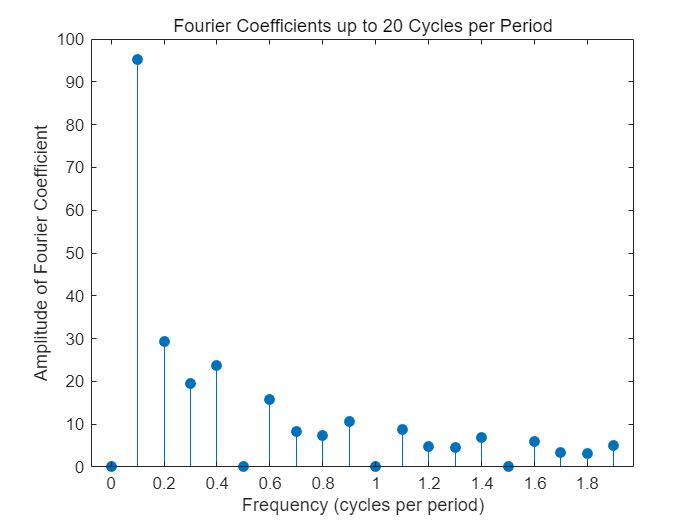

% ii
N = length(data); 
frequencies = (0:N-1)/N*20;

fft_result = fft(data);

num_freqs = 20;
fft_magnitude = abs(fft_result(1:num_freqs)); 

figure;
stem(frequencies(1:num_freqs), fft_magnitude, 'filled');
title('Fourier Coefficients up to 20 Cycles per Period');
xlabel('Frequency (cycles per period)');
ylabel('Amplitude of Fourier Coefficient');

function output = custom_conv2(img, mask)
    [m, n] = size(img);
    [k, l] = size(mask);
    pad_x = floor(k / 2);
    pad_y = floor(l / 2);
    img_padded = padarray(img, [pad_x, pad_y], 'replicate');
    output = zeros(m, n);
    for i = 1:m
        for j = 1:n
            region = img_padded(i:i+k-1, j:j+l-1);
            output(i, j) = sum(sum(region .* mask));
        end
    end
    output = output / sum(mask(:));
end

function output = contrast_stretch(img)
    min_val = double(min(img(:)));
    max_val = double(max(img(:)));
    output = (double(img) - min_val) * (255 / (max_val - min_val));
    output = uint8(output);
end

function zoomed_img = first_order_hold(img)
    [rows, cols] = size(img);
    zoomed_img = zeros(2*rows, 2*cols); 

    for i = 1:rows
        for j = 1:cols
            zoomed_img(2*i-1, 2*j-1) = img(i, j);
            zoomed_img(2*i-1, 2*j) = img(i, j);
            zoomed_img(2*i, 2*j-1) = img(i, j);
            zoomed_img(2*i, 2*j) = img(i, j);
        end
    end
    zoomed_img = uint8(zoomed_img);
end

function output = median_filter(img)
    [m, n] = size(img);
    output = zeros(m, n); 

    for i = 2:m-1
        for j = 2:n-1

            region = img(i-1:i+1, j-1:j+1);

            output(i, j) = median(region(:));
        end
    end
    output = uint8(output);
end